clc;clear all;
load('project.mat')

Visualize the Test just for implementation ideas

testvec = []; % [test1(1:100) test2(1:100) ... test150(1:100)]
for i = 1:5
    testvec = [testvec test{1,i}(1:200)'];
end
plot(testvec)
hold on
plot(train1(1:3000));
hold on
plot(train2(1:3000));
hold on
plot(train3(1:3000));
hold on
plot(train4(1:3000));
hold on
plot(train5(1:3000));
hold off
for i = 1:200:(30000/20)
    xline(i,'--','LabelHorizontalAlignment','left','LabelOrientation','horizontal','Label',sprintf('Test %d',floor(i/200)))
end
xlim([0 1050])
xlabel('Num Sample')
ylabel('Amplitude')

Short train vectors

st1 = train1(1:5000);
st2 = train2(1:5000);
st3 = train3(1:5000);
st4 = train4(1:5000);
st5 = train5(1:5000);

Frequency Analysis     

L = size(st1,1);

fst1 = fft(st1);
P2 = abs(fst1/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

fst2 = fft(st2);
P4 = abs(fst2/L);
P3 = P4(1:L/2+1);
P3(2:end-1) = 2*P3(2:end-1);

fst3 = fft(st3);
P6 = abs(fst3/L);
P5 = P6(1:L/2+1);
P5(2:end-1) = 2*P5(2:end-1);

fst4 = fft(st4);
P8 = abs(fst4/L);
P7 = P8(1:L/2+1);
P7(2:end-1) = 2*P7(2:end-1);

fst5 = fft(st5);
P10 = abs(fst5/L);
P9 = P10(1:L/2+1);
P9(2:end-1) = 2*P9(2:end-1);

findpeaks(P1,'MinPeakHeight',0.015);
hold on
findpeaks(P3,'MinPeakHeight',0.015);
hold on
findpeaks(P5,'MinPeakHeight',0.015);
hold on
findpeaks(P7,'MinPeakHeight',0.015);
hold on
findpeaks(P9,'MinPeakHeight',0.015);
hold off
xlim([0 100])
ylim([0 0.2])
xlabel('Frequency [Hz]')
ylabel('Amplitude [V]')
title('FFT of Train Examples')
legend('Ttrain1','Train1 Peaks','Train2','Train2 Peaks','Train3','Train3 Peaks','Train4','Train4 Peaks','Train5','Train5 Peaks')

peaksMat = [peaks1, peaks2, peaks3, peaks4, peaks5]'

Auto-correlation analysis

x1 = xcorr(st1);
minprom = 0.0005;
mindist_xunits = 0.3;
minpkdist = floor(mindist_xunits/(1/2));
findpeaks(x1,'minpeakprominence',minprom,'minpeakdistance',minpkdist);
hold on
[val,loc] = findpeaks(x1,'minpeakprominence',minprom,'minpeakdistance',minpkdist);
[~,idx] = maxk(val,2);
plot(loc(idx),val(idx),'o','LineWidth',1.5,'MarkerSize',20)
ylabel('Auto-Correlation result')
xlabel('Sample Number')
title('Autocorrelation of Train1')
hold off

PSD analysis

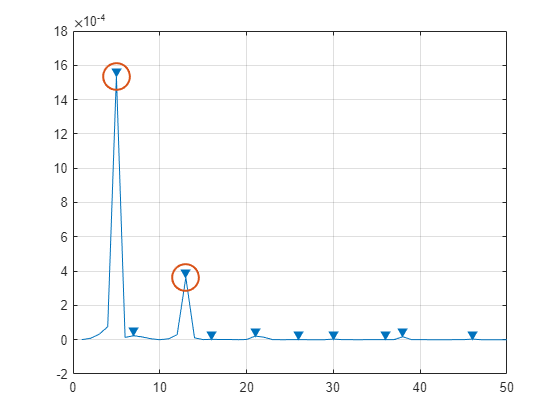

fs = 50000;
mindist_xunits = 0.3;
N = 4096;

[p, l] = pwelch(st1,rectwin(length(st1)),[],N,fs);
findpeaks(p,'npeaks',10)
hold on
[psdPeaks,locPSDpeak] = findpeaks(p,'npeaks',10);
[psdPeak,locinPSDValue] = maxk(psdPeaks,2);
plot(locPSDpeak(locinPSDValue),psdPeak,'o','LineWidth',1.5,'MarkerSize',20)
hold off
xlim([0 50])

Mean Values

st1mean = mean(st1)

RMS Values

st1rms = rms(st1)

Function Test

mat = [getFeatures(st1); getFeatures(st2); getFeatures(st3); getFeatures(st4); getFeatures(st5)]

mat =     0.1792    0.1023  111.7723   89.4028    0.0015    0.0004   -0.0002    0.1495
    0.1901    0.1120  128.8584  103.0836    0.0017    0.0004   -0.0001    0.1605
    0.1792    0.1043  114.1625   91.4671    0.0015    0.0003   -0.0001    0.1511
    0.1768    0.1041  112.4280   89.9516    0.0015    0.0004   -0.0001    0.1500
    0.1720    0.0980  103.3074   82.6480    0.0014    0.0003   -0.0002    0.1437
